# Map-Based Planning

Yimin Pan

#### Ex 4

**a) Create an obstacle map that contains a maze and solve it using distance transform.**

makemap:
  left button, click and drag to create a rectangle
  or type the following letters in the figure window:
  p - draw polygon
  c - draw circle
  e - erase map
  u - undo last action
  q - leave editing mode


point1 =    20.4190  119.0794


point2 =    20.1832   19.4907


point1 =    20.1832  117.2850


point2 =   111.1740  119.3785


point1 =   112.3527  119.3785


point2 =   111.8812   19.4907


point1 =    34.0912   19.4907


point2 =   110.4669   19.7897


point1 =    33.1483  102.6308


point2 =    33.1483   36.2383


point1 =    32.6768  103.2290


point2 =    95.6160  104.4252


point1 =    33.6197   35.9393


point2 =    97.0304   36.2383


point1 =    97.2661   86.4813


point2 =    97.2661   35.3411


point1 =    50.3564   87.6776


point2 =    49.8849   49.0981


point1 =    50.8278   88.2757


point2 =    79.3508   89.4720


point1 =    49.8849   48.2009


point2 =    69.2145   48.5000


point1 =    79.5866   88.2757


point2 =    80.0580   52.3879


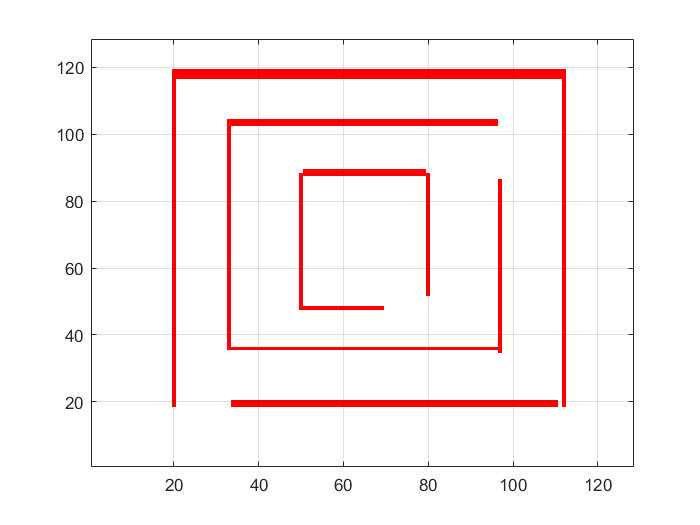

map = makemap();

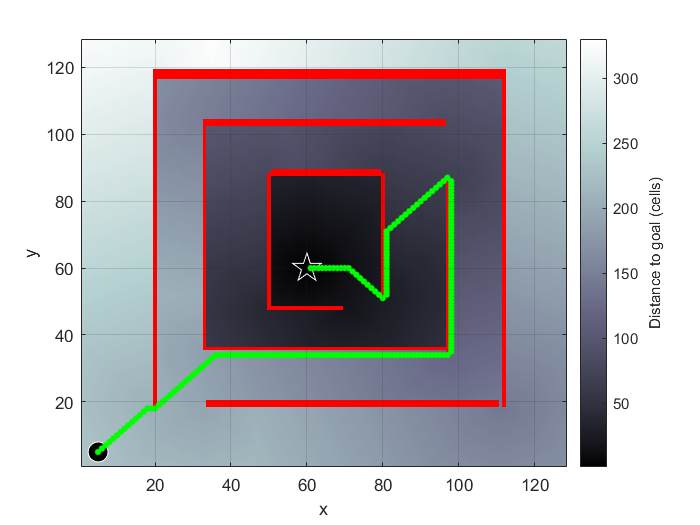

start = [5 5]; goal = [60 60];
dx = DXform(map);
dx.plan(goal);
dx.query(start, 'animate');

#### Ex 5

**a) Add a low cost region to the living room. Can you make the robot prefer to take this route to the kitchen?**

To guide the robot to the living room, we must set the cost of this area lower than other, so the robot will prioritize this route. For example to 0.1 while keeping the other areas to 1

load house
ds = Dstar(house);
ds.plan(place.kitchen);

245184 iterations


ds.modify_cost([220, 245 ; 110 250], 0.1);
ds.plan();

374469 iterations


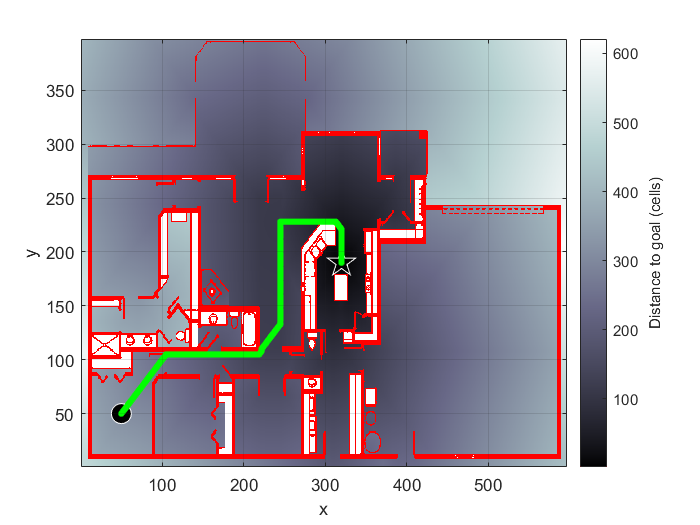

ds.query(place.br3, 'animate');

**b) Block additional doorways to challenge the robot.**

To block doorways, we simply set their cost to 'Inf'. Then the algorithm will treat it as obstacles. In this case we block the entry to the living room and the bottom door of the kitchen.

ds.plan(place.kitchen);

245184 iterations


ds.modify_cost([210, 250 ; 105 115], Inf);
ds.modify_cost([300,325; 115,125], Inf);
ds.plan();

167876 iterations


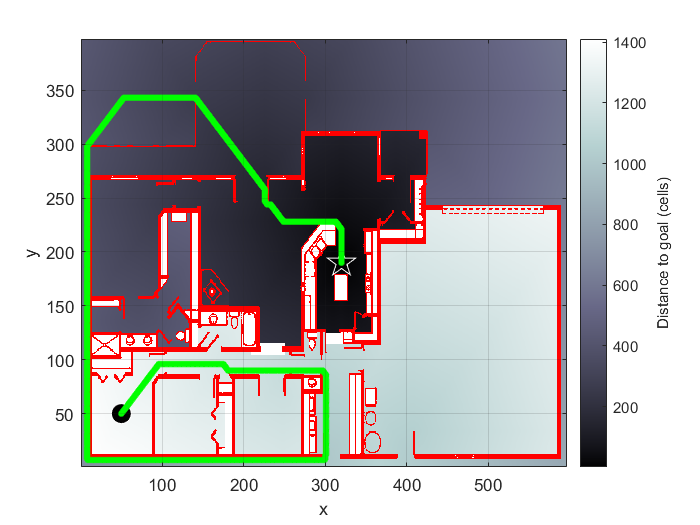

ds.query(place.br3, 'animate');

#### Ex 6

a) Run the PRM planner 100 times and gather statistics on the resulting path length.

We will run the planner 100 times (with 150 nodes), and calculate statistics on the number of connected components and edges.

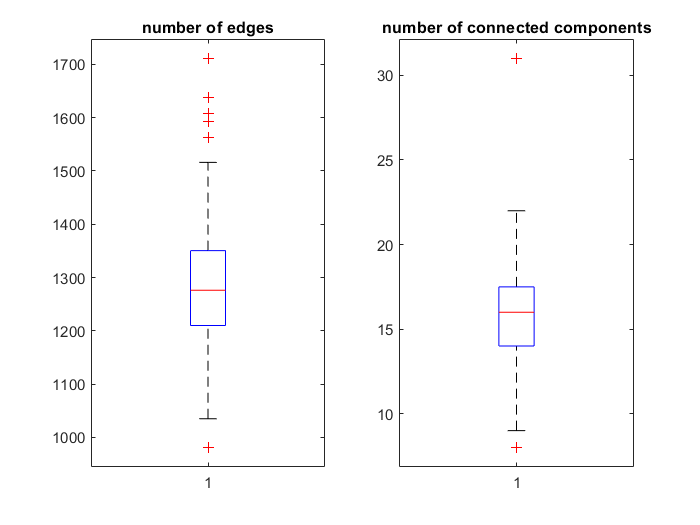

nEdges = [];
nCC = [];
for i = [1:100]
    prm = PRM(house);
    prm.plan('npoints', 150);
    nEdges(i) = prm.graph.ne;
    nCC(i) = prm.graph.nc;
end
figure; subplot(1,2,1); boxplot(nEdges); title("number of edges");
subplot(1,2,2); boxplot(nCC); title("number of connected components");

b) Vary the value of the distance threshold parameter and observe the effect.

As we can see in the plots, we can generate very different graphs by changing the distance threshold parameter. When this value is low, the distance between nodes are small, so we tend to have connected components of smaller coverage and hence we have lower probability of finding a path between start point and goal point. On the other hand, when this value is high, more area of the map is covered by the CCs and we can find a path easier.

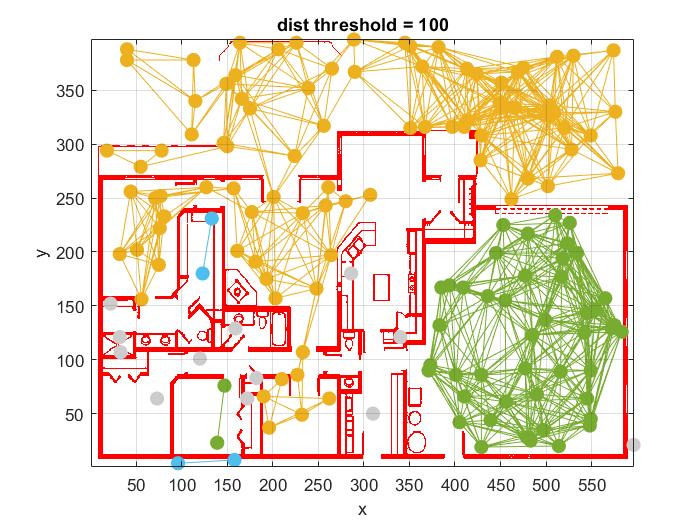

prm1 = PRM(house);
prm1.plan('npoints', 150, 'distthresh', 100);

prm2 = PRM(house);
prm2.plan('npoints', 150, 'distthresh', 200);

figure; subplot(1,2,1); prm1.plot(); title("dist threshold = 100");

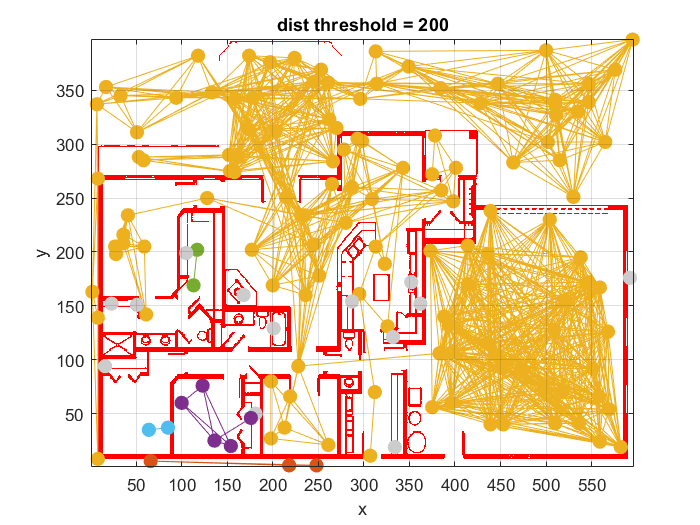

subplot(1,2,2); prm2.plot(); title("dist threshold = 200");

#### Ex 7

**a) How many iterations are required to completely fill the region of interest shown in Fig. 5.13c?**

With 6 itreations we obtained the same plot as the figure

lp = Lattice();
lp.plan('iterations', 6);

372 nodes created


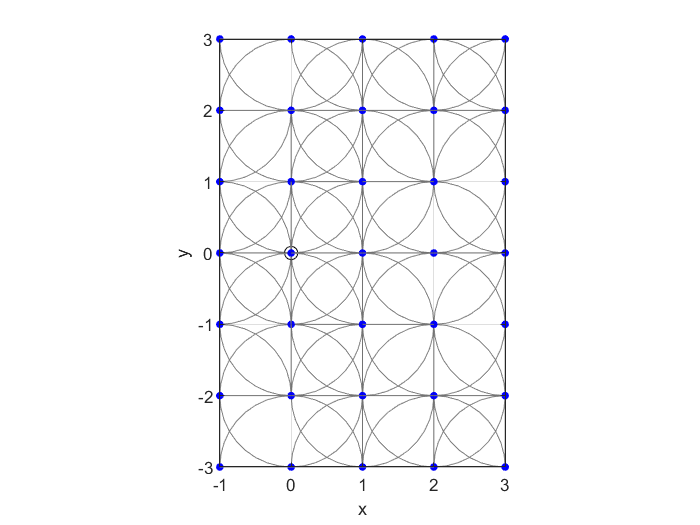

lp.plot();
xlim([-1 3])
ylim([-3 3])

**b) How does the number of nodes and the spatial extent of the lattice increase with the number of iterations?**

Exponential, as shown in the plots

its = [1:10];
nodes = [];
maxDist = [];
lp = Lattice();
for i = its
    lp.plan('iterations', i);
    nodes(i) = lp.graph.n;
    diffX = max(lp.graph.vertexlist(1,:))- min(lp.graph.vertexlist(1,:));
    diffY = max(lp.graph.vertexlist(2,:))- min(lp.graph.vertexlist(2,:));
    maxDist(i) = sqrt(diffX^2+diffY^2);
end

4 nodes created
13 nodes created
38 nodes created
97 nodes created
209 nodes created
372 nodes created
566 nodes created
780 nodes created
1020 nodes created
1292 nodes created


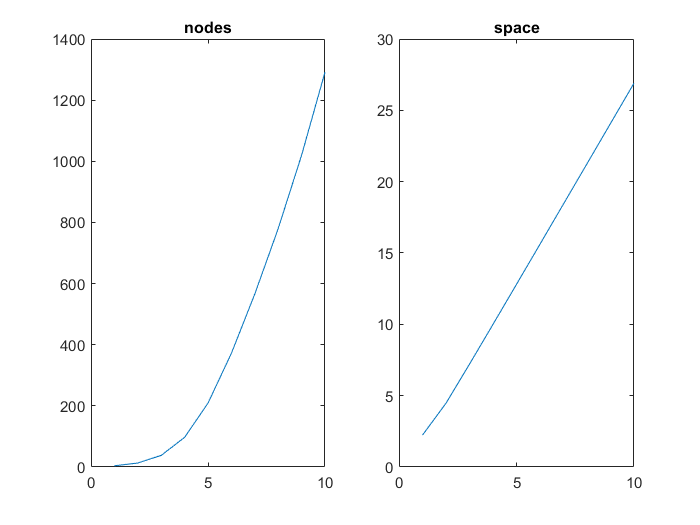

figure; subplot(1,2,1); plot(its,nodes); title('nodes');
subplot(1,2,2); plot(its,maxDist); title('space');

**c) Given a car with a wheelbase of 4.5 m and maximum steering angles of ±30 deg what is the smallest possible grid size?**

4.5/tand(30)

ans = 7.7942

**d) Redo Fig. 5.15b to achieve a path that uses only right hand turns.**

Can't achive a path with the given configuration, the are points not reachable with only right turns.

lp.plan('iterations', 8);

780 nodes created


lp.plan('cost', [Inf Inf 1]);

780 nodes created


lp.query([1 2 pi/2], [2 -2 pi/2]);

A* path cost Inf


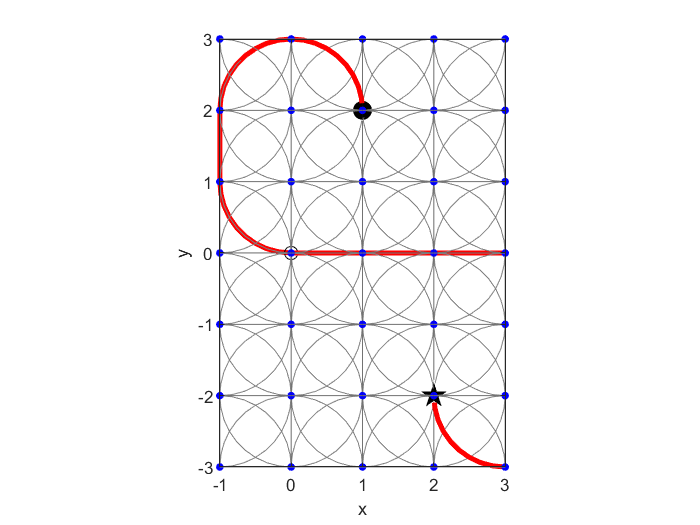

lp.plot();
xlim([-1 3])
ylim([-3 3])

**e) Compute curvature as a function of path length for a path through the lattice such as the one shown in Fig. 5.15a.**

lp.plan('cost', [1 1 1]);

780 nodes created


p = lp.query([1 2 pi/2], [2 -2 0]);

A* path cost 6


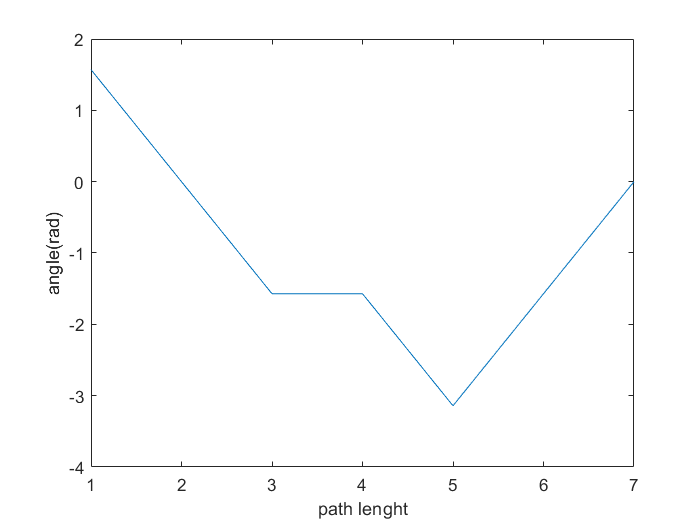

pLength = [1:length(p)];
plot(pLength, p(:,3)); ylabel("angle(rad)"); xlabel("path lenght");

#### Ex 8

**a) Find a path to implement a 3-point turn.**

load road;
car = Bicycle('steermax', 0.5);
rrt = RRT(car, road, 'npoints', 500, 'root', [50 22 0], 'simtime', 4)

 
rrt = 
RRT navigation class:                                    
  occupancy grid: 80x100                                 
  region: X 1.000000 : 100.000000; Y 1.000000 : 80.000000
  sim time: 4.000000                                     
  speed: 1.000000                                        
 Graph:                                                  
  3 dimensions                                           
  0 vertices                                             
  0 edges                                                
  0 components                                           
Bicycle object                                           
  L=1, steer.max=0.5, accel.max=Inf                      
  Superclass: Vehicle                                    
    max speed=1, dT=0.1, nhist=0                         
    configuration: x=0, y=0, theta=0                     


rrt.plan();

p1 = rrt.query([10 40 0], [35 60 pi/4]);

A* path cost 15


p2 = rrt.query([35 60 pi/4], [25 40 3*pi/4]);

A* path cost 4


p3 = rrt.query([25 40 3*pi/4], [10 60 pi]);

A* path cost 18


p = rrt.query([10 40 0], [10 60 pi]);

A* path cost 13


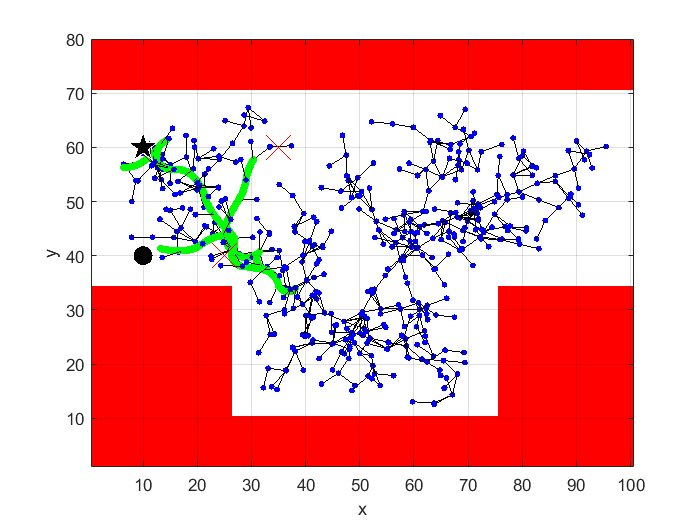

rrt.plot([p1;p2;p3]);
hold on;
plot(35, 60, 'xr', 'MarkerSize',20);
plot(25, 40, 'xr', 'MarkerSize',20);

**b) Experiment with RRT parameters such as the number of points, the vehicle steering angle limits, and the path integration time.**

Number of points fixes the quanity of nodes of the generated graph. Steering angle limit the level of freedom (of the angle) of connections between nodes, and the simulation time limit the length of an edge, namely the distance between two points. Increasing the value of these parameters we end up with a grapth that covers more areas of the map.

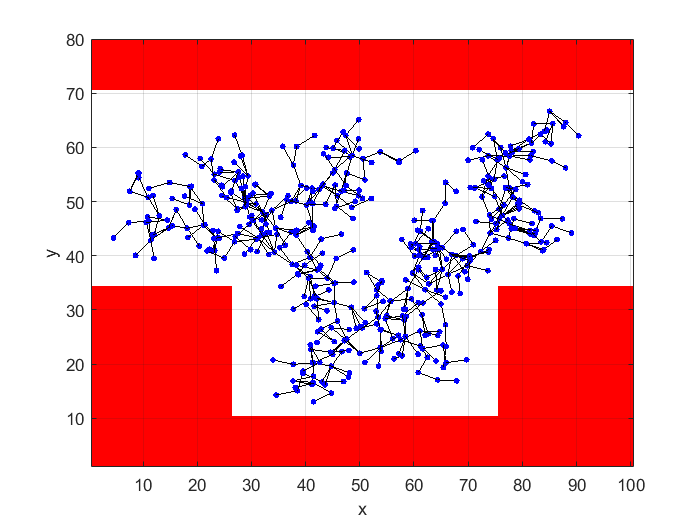

car = Bicycle('steermax', 0.5);
rrt = RRT(car, road, 'npoints', 500, 'root', [50 22 0], 'simtime', 4);
rrt.plan();
rrt.plot();
car = Bicycle('steermax', pi);
rrt = RRT(car, road, 'npoints', 500, 'root', [50 22 0], 'simtime', 10);
rrt.plan();

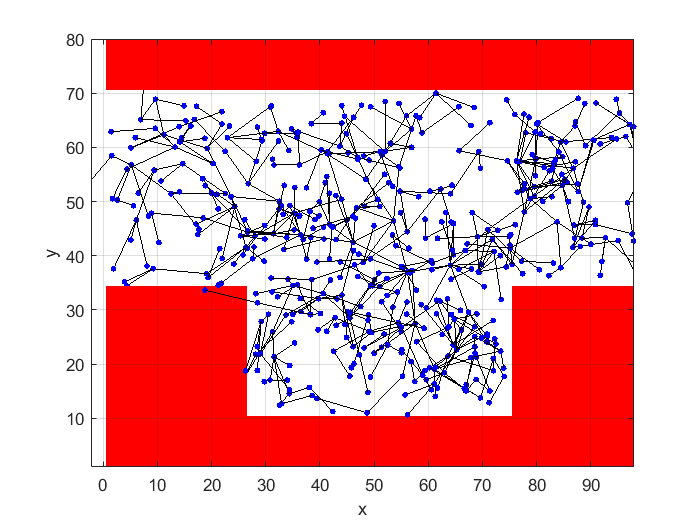

rrt.plot();

**c) Additional information in the node of each graph holds the control input that was computed to reach the node. Plot the steering angle and velocity sequence required to move from start to goal pose.**

vel = [];
steer = [];
car = Bicycle('steermax', 0.5);
rrt = RRT(car, road, 'npoints', 1000, 'root', [50 22 0], 'simtime', 4);
rrt.plan();

p = rrt.query([40 45 0], [50 22 0]);

A* path cost 12


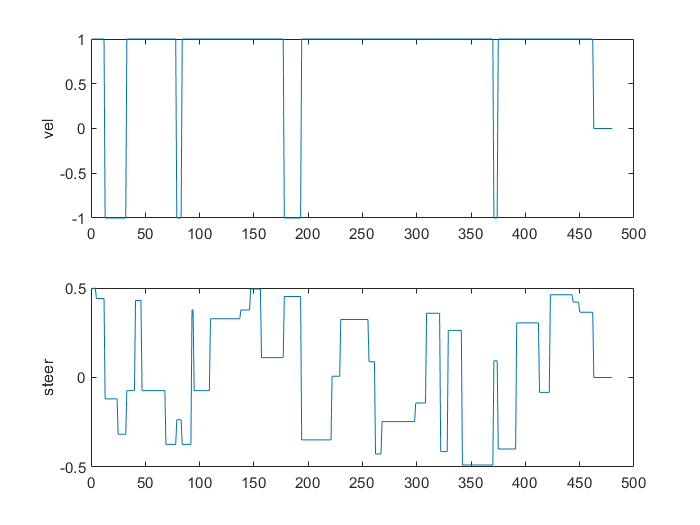

for i = [1:length(p)]
    diff = abs(rrt.graph.vertexlist'- p(i,:));
    [val, idx] = min(diff(:,1)+diff(:,2)+diff(:,3));
    if isfield(rrt.graph.vertexdata{idx}, 'vel') 
        vel(i) = rrt.graph.vertexdata{idx}.vel;
    else
        vel(i) = 0;
    end 
    if isfield(rrt.graph.vertexdata{idx}, 'steer') 
        steer(i) = rrt.graph.vertexdata{idx}.steer;
    else
        steer(i) = 0;
    end 
end
figure; subplot(2,1,1); plot([1:length(p)], vel); ylabel("vel");
subplot(2,1,2); plot([1:length(p)], steer); ylabel("steer");

**d) Add a local planner to move from initial pose to the closest vertex, and from the final vertex to the goal pose.**

start = [40 45 0];
goal = [50 22 0];
rrt.plan();
vertexList = rrt.graph.vertexlist';
closestVertex = findClosest(start, vertexList);
p1 = rrt.query(start, closestVertex);

A* path cost 2


p2 = rrt.query(closestVertex, goal);

A* path cost 9


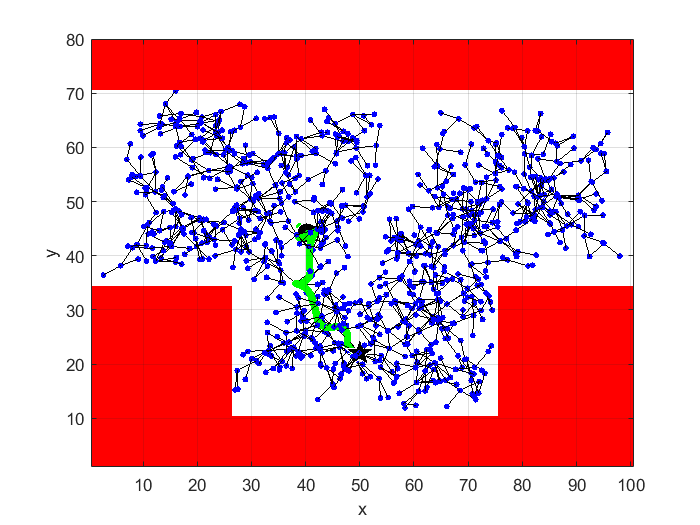

rrt.plot([p1;p2]);

**e) Determine a path through the graph that minimizes the number of reversals of direction.**

rrt = RRT(car, road, 'npoints', 2000, 'root', [50 22 0], 'simtime', 4);
rrt.plan();
start = [40 45 0];
goal = [50 22 0];
points = [0:0.2:1];
diffs = (goal-start).*points'; % points in the line from star to goal
path = [];


path =

     []



for i = [1:length(diffs)-1]
     act = start+diffs(i,:);
     next = start+diffs(i+1,:);
     actPath = rrt.query(act, next);
     path = [path; actPath];
end

A* path cost 6
A* path cost 0
A* path cost 9
A* path cost 9
A* path cost 7


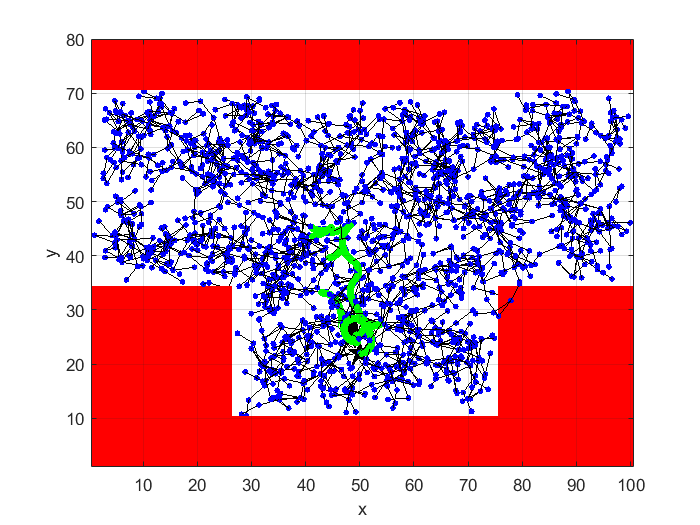

rrt.plot(path);

function [pose, idx] = findClosest(vertex, vertexList)
    diff = abs(vertexList- vertex);
    [~, idx] = min(diff(:,1)+diff(:,2)+diff(:,3));
    pose = vertexList(idx,:);
end

function output = same(v1, v2)
    output = (v1(1) == v2(1)) && (v1(2) == v2(2));
end